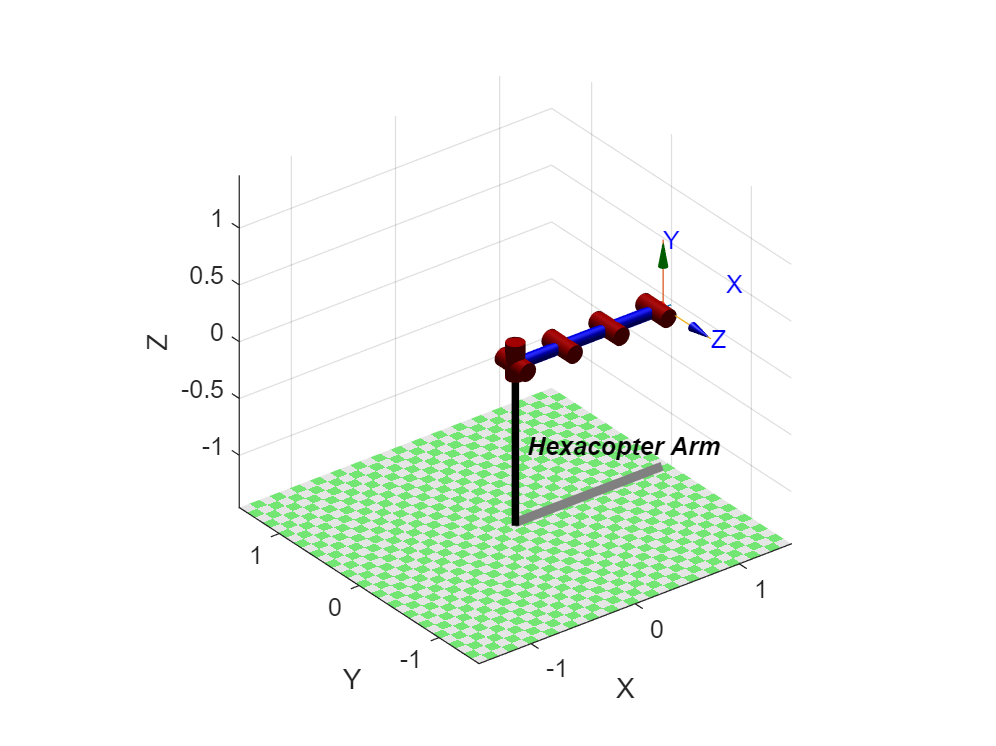

%1a--------DH--------%
clear
syms q1 q2 q3 q4 q5 

%Defining link-lengths. All values [m]
L1 = .04; L2 = .45; L3 = .45; L4 = .45; L5 = .07;

%Creating zero angle variable
qz = ([0 0 0 0 0 ]);

%% 1a
%Connecting the links with the DH-parameters: 
%| theta | d | a | alfa |  
L(1) = Link ( [0 -L1 0 pi/2]);
L(2) = Link ( [0 0 L2 0] );
L(3) = Link ( [0 0 L3 0] );
L(4) = Link ( [0 0 L4 0] );
L(5) = Link ( [0 0 L5 0] );

%Creating an object of the DH-parameters 
RobotArm = SerialLink(L);
RobotArm.name = 'Hexacopter Arm';

%plotting our arm with all angles set to zero
RobotArm.plot(qz)

%2ai.iii------------Show equivalence------------%
Q1 = 0; Q2 = 0; Q3 = 0; Q4 = 0; Q5 = 0; 
Qz = [Q1 Q2 Q3 Q4 Q5];

T01 = [cos(Q1), -sin(Q1), 0, 0; 
    sin(Q1), cos(Q1), 0, 0; 
    0, 0, 1, -1/25; 
    0, 0, 0, 1];
T12 = [cos(Q2), -sin(Q2), 0, 9/20; 
    0, 0, -1, 0; 
    sin(Q2), cos(Q2), 0, 0; 
    0, 0, 0, 1];
T23 = [cos(Q3), -sin(Q3), 0, 9/20; 
    sin(Q3), cos(Q3), 0, 0; 
    0, 0, 1, 0; 
    0, 0, 0, 1];
T34 = [cos(Q4), -sin(Q4), 0, 9/20; 
    sin(Q4), cos(Q4), 0, 0; 
    0, 0, 1, 0; 
    0, 0, 0, 1];
T45 = [cos(Q5), -sin(Q5), 0, 7/100;
    sin(Q5), cos(Q5), 0, 0;
    0, 0, 1, 0; 
    0, 0, 0, 1];

T05Manually = T01*T12*T23*T34*T45

T05Manually =     1.0000         0         0    1.4200
         0         0   -1.0000         0
         0    1.0000         0   -0.0400
         0         0         0    1.0000


T05dh = RobotArm.fkine(qz)

 

T05dh = 
         1         0         0      1.42
         0         0        -1         0
         0         1         0     -0.04
         0         0         0         1


qFromInverseKinematics = RobotArm.ikine(T05dh, 'mask', [1 1 1 0 0 0])

qFromInverseKinematics =      0     0     0     0     0


%  {B} => Base;   {C} => Camera;  {F} => Fruit;

R = eye(3);

% from {B} to {E}
bPe = [0.24 0 0.7];
bTe = rt2tr(R, bPe)

bTe =     1.0000         0         0    0.2400
         0    1.0000         0         0
         0         0    1.0000    0.7000
         0         0         0    1.0000


% from {B} to {C}
bPc = [0.24 0 0.7];
bTc = rt2tr(R, bPc)

bTc =     1.0000         0         0    0.2400
         0    1.0000         0         0
         0         0    1.0000    0.7000
         0         0         0    1.0000


% from {C} to {F}
cPf = [1.40 0 0];
cTf = rt2tr(R, cPf)

cTf =     1.0000         0         0    1.4000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


eTf = inv(bTe)*bTc*cTf

eTf =     1.0000         0         0    1.4000
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


% finding angles
qFruit = RobotArm.ikine(eTf,'mask',[1 1 1 0 0 1])

qFruit =    -0.0000   -0.1160    0.3846   -0.3295    0.0609


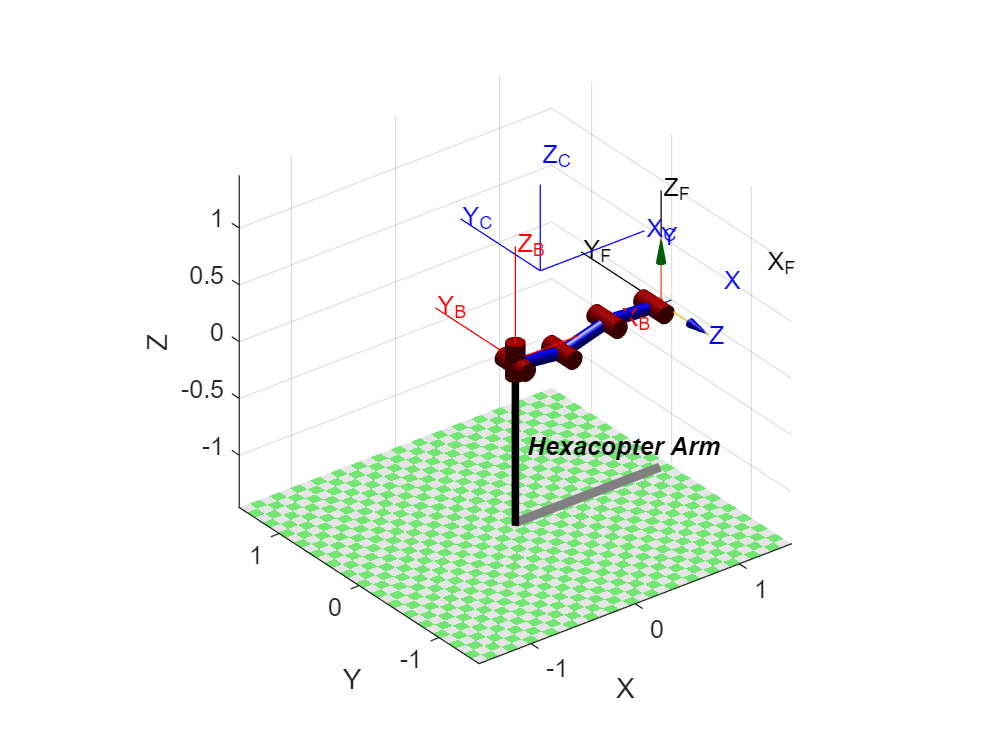

%...............Ploting frames...............%

%base frame 
hold on
trplot(eye(3),'color','r','frame','B')

%camera frame
trplot(bTc,'color','b','frame','C')

%fruit frame
trplot(cTf,'color','k','frame','F')
RobotArm.plot(qFruit)

grid on

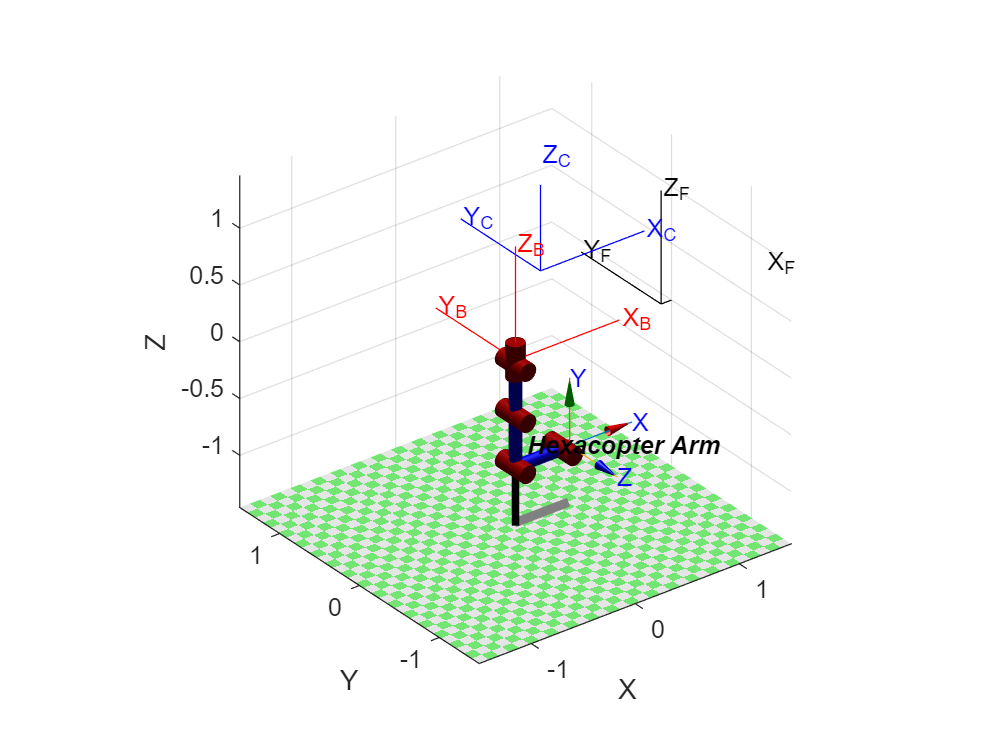

%............Trajectory planning................% 
t = [0:0.05:2];

qStep1 = [0 -pi/2 0 pi/2 0];                              % flying position without fruit     
qStep2 = [0 deg2rad(-60) deg2rad(120) deg2rad(-60)  0];   % fruit detected
qStep3 = qFruit;                                          % reaching fruit
qStep4 = qStep2;                                          % picking the fruit
qStep5 = [0 -pi/2 0 pi/2  pi/2];                          % flying position with fruit
qStep6 = [0 -pi/2 0 0 0];                                 % drop-off position


%.......Making joint and cartesian trajectories......% 
jtFruitDetected = jtraj(qStep1, qStep2, t);
jtReachFruit    = jtraj(qStep2, qStep3, t);
jtPickFruit     = jtraj(qStep3, qStep4, t/2);
jtFlyLoad       = jtraj(qStep4, qStep5, t);
jtDropOff       = jtraj(qStep5, qStep6, t);
jtFlyEmpty      = jtraj(qStep6, qStep1, t);


%......Plotting trajectories........................% 
RobotArm.plot(jtFruitDetected); RobotArm.plot(jtReachFruit); RobotArm.plot(jtPickFruit);
RobotArm.plot(jtFlyLoad); RobotArm.plot(jtDropOff); RobotArm.plot(jtFlyEmpty);